## Task 2.12

colorintrinsics = determineIntrinsics;
ppx = colorintrinsics.ppx

ppx = 950.7278

ppy = colorintrinsics.ppy

ppy = 533.0599

fx = colorintrinsics.fx

fx = 1.4089e+03

fy = colorintrinsics.fy

fy = 1.4089e+03

colorintrinsics.width;

Explain eacxh entry (left to do)

## Task 2.13

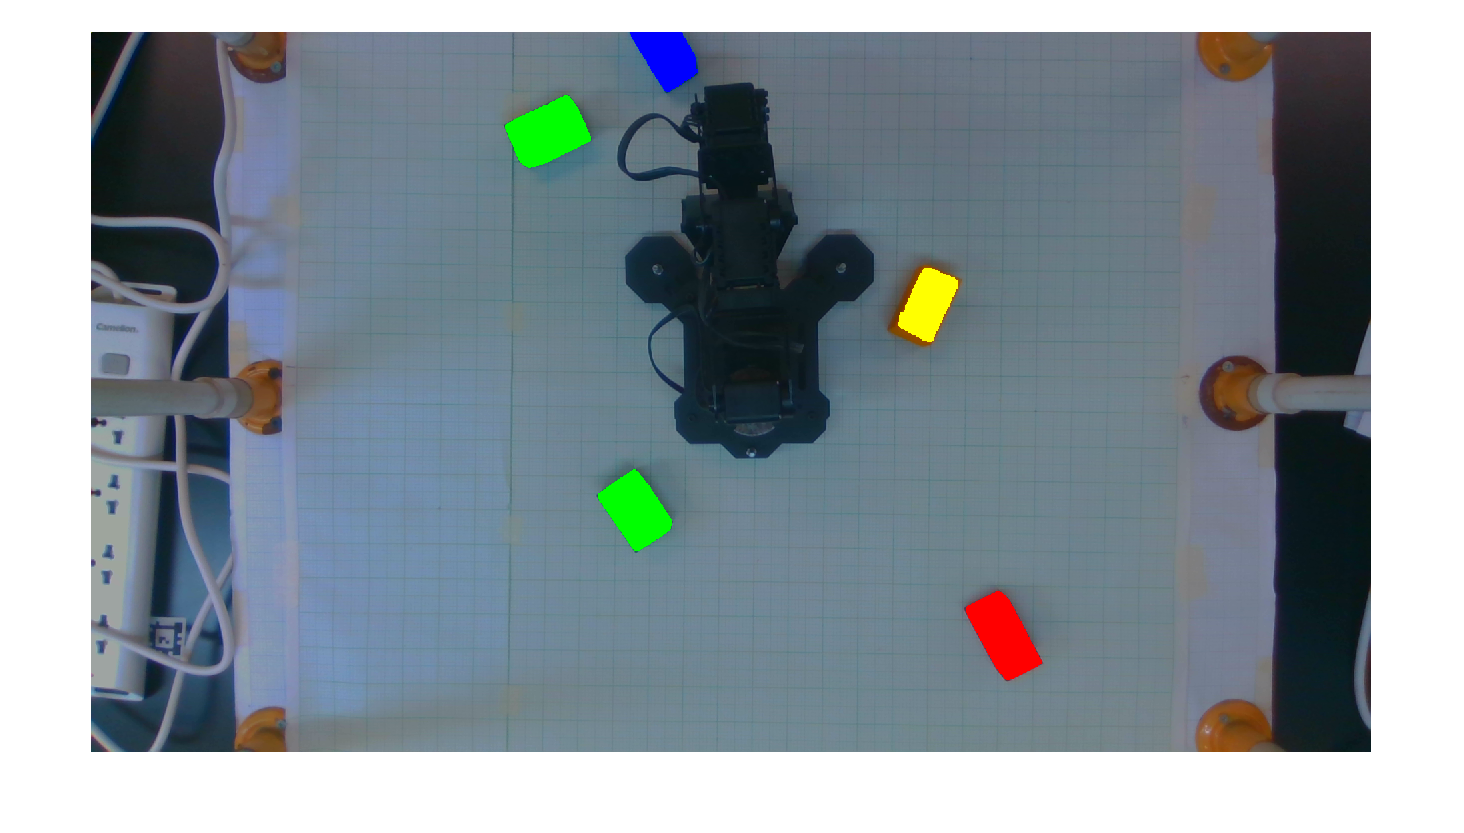

% determineIntrinsics;
% Reading the image
img1 = imread("intro to rob\at3_Color.png");
imshow(img1)


cam_intrinsics = cameraIntrinsics([fx fy],[ppx ppy], [1080 1920]);

[tag, loc,  pose] = readAprilTag(img1, "tagStandard41h12", cam_intrinsics, 2.3);

I = img1;
for idx = 1:length(tag)
    % Display the ID and tag family
    disp("Detected Tag ID, Family: " + tag(idx))
        % + ", " ...
        %     + detectedFamily(idx));
 
    % Insert markers to indicate the locations
    markerRadius = 8;
    numCorners = size(loc,1);
    markerPosition = [loc(:,:,idx),repmat(markerRadius,numCorners,1)];
    I = insertShape(I,"FilledCircle",markerPosition,ShapeColor="red",Opacity=1);
end

Detected Tag ID, Family: 0
Detected Tag ID, Family: 1
Detected Tag ID, Family: 2
Detected Tag ID, Family: 3


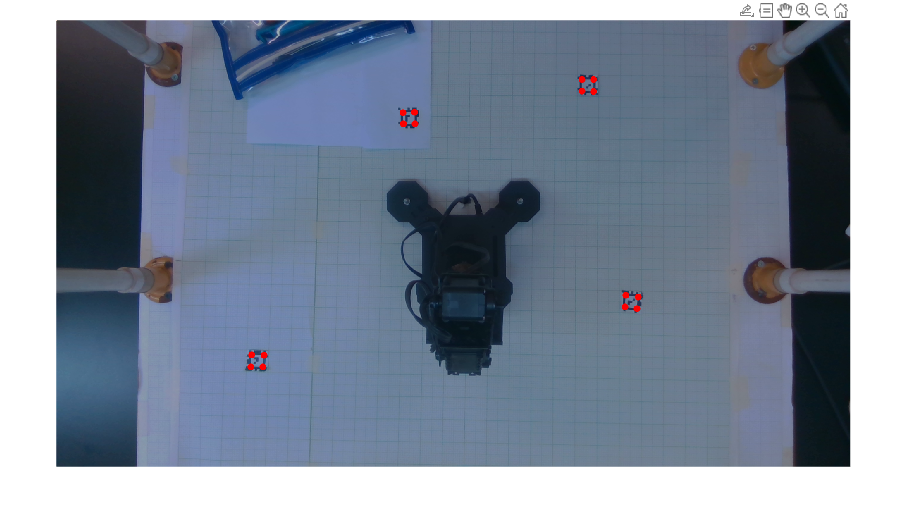


imshow(I)

t = pose(1).Translation

t =   -37.7062   23.5615  114.2910


r = pose(1).R

r =     0.0300   -0.8762   -0.4810
    0.9520   -0.1216    0.2809
   -0.3046   -0.4663    0.8305


a = pose(1).A

a =     0.0300   -0.8762   -0.4810  -37.7062
    0.9520   -0.1216    0.2809   23.5615
   -0.3046   -0.4663    0.8305  114.2910
         0         0         0    1.0000


d = pose(1).Dimensionality

d = 3



t = pose(2).Translation

t =    27.1565  -30.5649  114.5382


r = pose(2).R

r =    -0.1130    0.8808    0.4598
   -0.8619    0.1433   -0.4863
   -0.4943   -0.4513    0.7430


a = pose(2).A

a =    -0.1130    0.8808    0.4598   27.1565
   -0.8619    0.1433   -0.4863  -30.5649
   -0.4943   -0.4513    0.7430  114.5382
         0         0         0    1.0000


d = pose(2).Dimensionality

d = 3


t = pose(3).Translation

t =    35.5280   11.9516  113.7765


r = pose(3).R

r =    -0.8830    0.0477    0.4669
   -0.0818   -0.9952   -0.0531
    0.4621   -0.0851    0.8827


a = pose(3).A

a =    -0.8830    0.0477    0.4669   35.5280
   -0.0818   -0.9952   -0.0531   11.9516
    0.4621   -0.0851    0.8827  113.7765
         0         0         0    1.0000


d = pose(3).Dimensionality

d = 3


t = pose(4).Translation

t =    -8.1507  -24.5873  116.8234


r = pose(4).R

r =     0.0029    0.9980   -0.0628
   -0.9628   -0.0142   -0.2699
   -0.2703    0.0613    0.9608


a = pose(4).A

a =     0.0029    0.9980   -0.0628   -8.1507
   -0.9628   -0.0142   -0.2699  -24.5873
   -0.2703    0.0613    0.9608  116.8234
         0         0         0    1.0000


d = pose(4).Dimensionality

d = 3

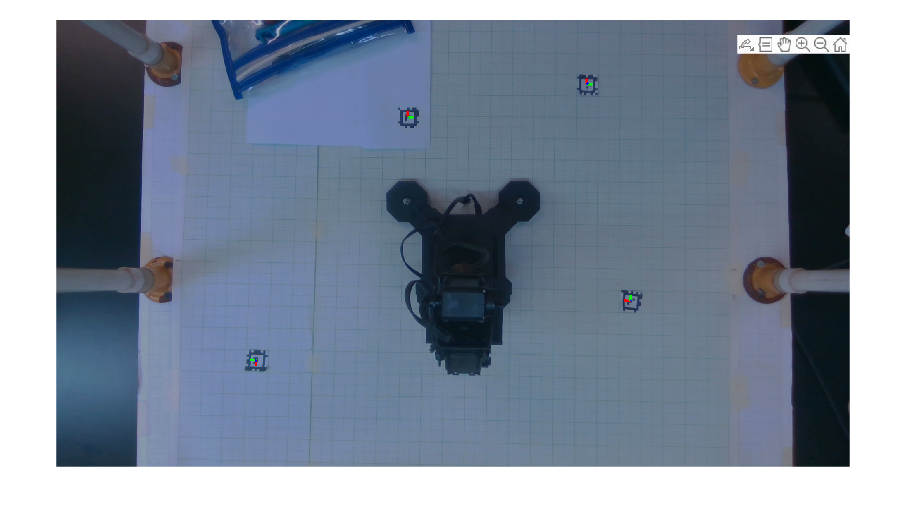

tagSize = 2.3;

worldPoints = [0 0 0; tagSize/2 0 0; 0 tagSize/2 0; 0 0 tagSize/2];
I = img1;

for i = 1:length(pose)
    % Get image coordinates for axes.
    imagePoints = world2img(worldPoints,pose(i),cam_intrinsics);

    % Draw colored axes.
    I = insertShape(I,Line=[imagePoints(1,:) imagePoints(2,:); ...
        imagePoints(1,:) imagePoints(3,:); imagePoints(1,:) imagePoints(4,:)], ...
        ShapeColor=["red","green","blue"],LineWidth=7);

    % I = insertText(I,loc(1,:,i),tag(i),BoxOpacity=1,FontSize=25);
end

imshow(I)

Task 2.17    

Dimensions of cube 29mm x 50mm (Rectangle face)

Depth 29mm

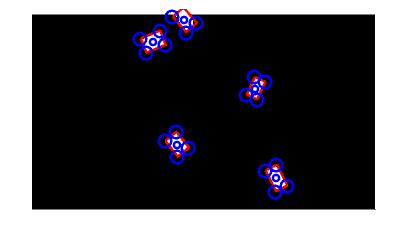


center = [1920/2, 1080/2, 0]; % camera and depth intrisics se ayen ge ye

[label, rgblabel, overlayingimg, CC, poses] = segment_objects("intro to rob\test_again_Color.png", "all", "intro to rob\test_bg_Color.png", true, center);

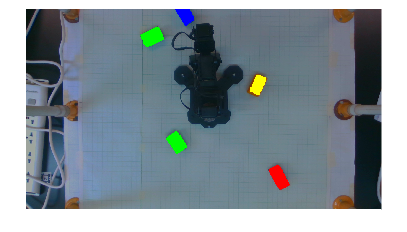


imshow(overlayingimg);

% pt = find_pixel_cords(center, [0, 0]);


% calculating homogenous transform 
pose = poses(1, :);
cTb = homogenous_transform(pose)

cTb =     0.9270   -0.3751         0 -274.0980
    0.3751    0.9270         0  388.8075
         0         0    1.0000         0
         0         0         0    1.0000


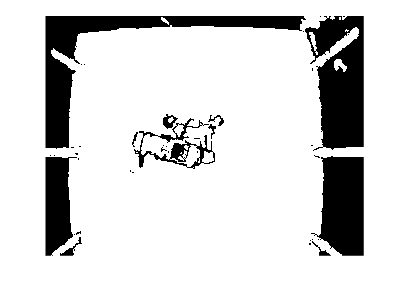

ptCloud = 0

[x,im,a,b,c] = pointcloud_example();

imwrite(im, "./intro to rob/bgfeb13.png");

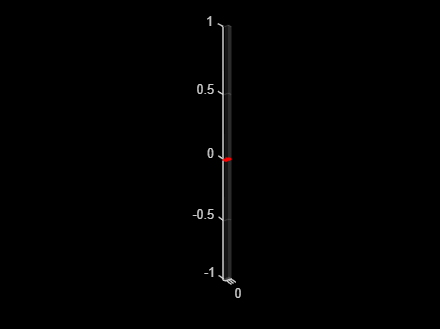

% Define the limits
XLimits = [-0.3882 0.5204];
YLimits = [-0.4813 0.3515];

% Create coordinate vectors
x = linspace(XLimits(1), XLimits(2), 640);
y = linspace(YLimits(1), YLimits(2), 480);

% Generate random perturbations
perturbations = -1.* (rand(1, 640) - 1) * 0.01;
% Add perturbations to the original vector
nonUniformVectorx = x + perturbations;

% Generate random perturbations
perturbations = (rand(1, 480)) * 0.02;
% Add perturbations to the original vector
nonUniformVectory = y + perturbations;

% Generate grid matrices using ndgrid
[X, Y] = ndgrid(nonUniformVectorx, nonUniformVectory);

% Define the rectangle boundaries
halfWidth = 0.05 / 2;   % 0.025 meters
halfHeight = 0.029 / 2; % 0.0145 meters

% Create a logical mask for points inside the rectangle
mask = (X >= -halfWidth) & (X <= halfWidth) & ...
       (Y >= -halfHeight) & (Y <= halfHeight);

% Initialize the point cloud with NaNs
pointCloudd = NaN(640, 480, 3);

% Assign coordinates only where the mask is true
pointCloudd(:,:,1) = X;      % X coordinates
pointCloudd(:,:,2) = Y;      % Y coordinates
pointCloudd(:,:,3) = 0;      % Z coordinates (0 for all points initially)

% Set all points outside the mask to NaN in all channels
mask3d = repmat(mask, 1, 1, 3);  % Replicate mask across the 3 channels
pointCloudd(~mask3d) = NaN;
figure;
pointCloudd = pointCloud(pointCloudd, "Color", "red");
pcshow(pointCloudd);

pcwrite(pointCloudd, "facemodelnonlinear.ply");

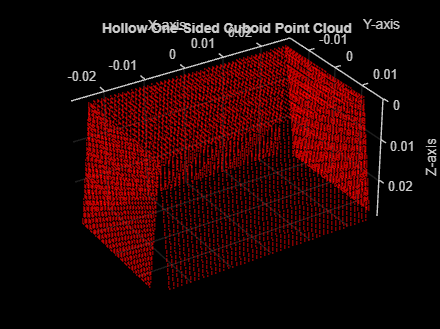

% Define the dimensions of the cuboid
width = 0.05;   % Width along X-axis (meters)
height = 0.029; % Height along Y-axis (meters)
depth = 0.029;  % Depth along Z-axis (meters)

% Define the resolution of the point cloud (number of points per dimension)
resolution = 50;

% Create coordinate vectors for each dimension
x = linspace(-width/2, width/2, resolution);
y = linspace(-height/2, height/2, resolution);
z = linspace(0, depth, resolution); % Z starts at 0 for the bottom face

% Generate grid matrices for each face
[X, Y] = meshgrid(x, y);
[Zx, Zy] = meshgrid(z, y);
[Xz, Yz] = meshgrid(x, z);

% Create the six faces of the cuboid
% Face 1: Front face (Z = depth)
frontFace = [X(:), Y(:), depth * ones(size(X(:)))];

% Face 2: Back face (Z = 0)
Z =  zeros(size(X(:)));
backFace = [X(:), Y(:), Z];

% Face 3: Left face (X = -width/2)
xl = -width/2 * ones(size(Zx(:))) - 0.1*Zx(:);
leftFace = [xl(:), Zy(:), Zx(:)];

% Face 4: Right face (X = width/2)

xl = width/2 * ones(size(Zx(:))) + 0.1*Zx(:);
rightFace = [xl(:), Zy(:), Zx(:)];

% Face 5: Bottom face (Y = -height/2)
yb = -height/2 * ones(size(Yz(:))) - 0.1.*Yz(:);
bottomFace = [Xz(:), yb(:), Yz(:)];

% Face 6: Top face (Y = height/2)
yb = height/2 * ones(size(Yz(:))) + 0.1.*Yz(:);
topFace = [Xz(:), yb(:), Yz(:)];

% Remove one face to make the cuboid one-sided (e.g., remove the back face)
% Combine the remaining five faces
pointCloudData = [backFace; leftFace; rightFace; bottomFace; topFace];

% Convert to a pointCloud object
cuboidPointCloud = pointCloud(pointCloudData, "Color", "red");

% Visualize the point cloud
figure;
pcshow(cuboidPointCloud, "VerticalAxisDir","Down");
title('Hollow One-Sided Cuboid Point Cloud');
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

% 
% % Save the point cloud to a file
pcwrite(cuboidPointCloud, 'cuboid.ply');

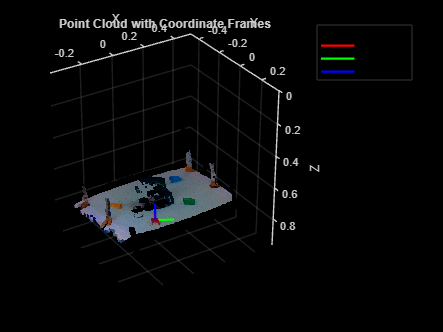

% Assuming you have a 1x5 array of rigid3d objects called 'rigidTransforms'
% rigidTransforms = [rigid3d1, rigid3d2, rigid3d3, rigid3d4, rigid3d5];
rigidTransforms = transforms;

% Assuming you have:
% - A point cloud of the scene called 'scenePointCloud' (Mx3 matrix)
% - A 1x5 array of rigid3d objects called 'rigidTransforms'

scenePointCloud = pcfromdepth(depth_frame,1/depth_scaling,intrinsics, ColorImage=color_frame, DepthRange=[0 1]);

% Define the original coordinate frame (unit vectors along x, y, z)
origin = [0; 0; 0]; % Origin of the frame
xAxis = [0.1; 0; 0];  % X-axis vector
yAxis = [0; 0.1; 0];  % Y-axis vector
zAxis = [0; 0; -0.1];  % Z-axis vector

% Create a figure for visualization
figure;
hold on;

% Visualize the original point cloud
pcshow(scenePointCloud, 'MarkerSize', 30, "VerticalAxisDir","Down"); % Adjust marker size as needed
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Point Cloud with Coordinate Frames');

% Loop through each rigid3d object and plot the transformed frame
for i = 1:length(rigidTransforms)
    % Get the current rigid transformation
    tform = rigidTransforms(i);
    
    % Transform the origin and axes using the rigid transformation
    transformedOrigin = transformPointsForward(tform, origin');
    transformedXAxis = transformPointsForward(tform, xAxis');
    transformedYAxis = transformPointsForward(tform, yAxis');
    transformedZAxis = transformPointsForward(tform, zAxis');
    
    % Plot the transformed X-axis (red)
    plot3([transformedOrigin(1), transformedXAxis(1)], ...
          [transformedOrigin(2), transformedXAxis(2)], ...
          [transformedOrigin(3), transformedXAxis(3)], 'r', 'LineWidth', 2);
    
    % Plot the transformed Y-axis (green)
    plot3([transformedOrigin(1), transformedYAxis(1)], ...
          [transformedOrigin(2), transformedYAxis(2)], ...
          [transformedOrigin(3), transformedYAxis(3)], 'g', 'LineWidth', 2);
    
    % Plot the transformed Z-axis (blue)
    plot3([transformedOrigin(1), transformedZAxis(1)], ...
          [transformedOrigin(2), transformedZAxis(2)], ...
          [transformedOrigin(3), transformedZAxis(3)], 'b', 'LineWidth', 2);
end

% Add a legend for the axes
legend('Point Cloud', 'X-axis', 'Y-axis', 'Z-axis');
axis equal;
grid on;
hold off;

function T = homogenous_transform(pose)
    x = pose(1);
    y = pose(2);
    theta = pose(3);

    T = [cos(theta), -sin(theta) 0 x;
         sin(theta),  cos(theta) 0 y;
         0 0 1 0;
         0 0 0 1];

end

function [label, rgblabel, overlayimg, CC, center_pts] = segment_objects(img_path, color, bg_path, bgFilter, cam_center)
    % Reading the image
    img1 = imread(img_path);
    bg = imread(bg_path);

    % Convert images to double precision for accurate subtraction
    bg = double(bg);
    fg = double(img1);

    % Perform subtraction for each RGB channel
    diffR = abs(fg(:,:,1) - bg(:,:,1));
    diffG = abs(fg(:,:,2) - bg(:,:,2));
    diffB = abs(fg(:,:,3) - bg(:,:,3));

    % Normalize differences
    diffR = diffR / max(diffR(:));
    diffG = diffG / max(diffG(:));
    diffB = diffB / max(diffB(:));

    % Create binary masks for each channel using adaptive thresholds
    maskR = diffR > 0.5;  % Adjust threshold as needed
    maskG = diffG > 0.5;
    maskB = diffB > 0.5;

    % Combine masks (logical OR) to detect foreground
    bw_mask = maskR | maskG | maskB;

    % Clean the mask with morphological operations
    bw_mask = imopen(bw_mask, strel('disk', 3)); % Remove noise
    bw_mask = imfill(bw_mask, 'holes'); % Fill small gaps

    % Apply mask to each RGB channel

    % Convert back to uint8
    fg_no_bg = uint8(fg); 
    for c = 1:3
        fg_no_bg(:,:,c) = uint8(fg(:,:,c) .* bw_mask);
    end
    img2 = img1;
    if bgFilter == true
        img1 = fg_no_bg;
    end
    
    % Converting rgb to LAB
    img1lab = rgb2lab(img1);
    [l a b] = imsplit(img1lab);

    % Converting rgb to HSV
    img1hsv = rgb2hsv(img1);
    [h s v] = imsplit(img1hsv);

    % creating empty masks
    sz = size(img1(:,:,1));
    redmask = zeros(sz);
    yellowmask = zeros(sz);
    greenmask = zeros(sz);
    bluemask = zeros(sz);

    if color == "red" | color == "all"
        redmask = h > 0.9 & s > 0.5 ;
        redmask = imfill(redmask, "holes"); % filling holes
        redmask = bwareaopen(redmask, 200); % size of actual box around 8200
        SE = strel("disk", 3); % creating a disk strel
        redmask = imclose(redmask, SE); % perofrming close operation to smoothen edges
        % imshow(redmask);
    end

    if color == "yellow" | color == "all"
        % h extracts color, s extracts regions of yellow with ihgh saturation and v
        % ignores the dark yellow areas of the camera stand
        yellowmask = s > 0.5 & h < 0.105 & v > 0.45;
        yellowmask = imfill(yellowmask, "holes"); % as above
        yellowmask = bwareaopen(yellowmask, 200);
        SE = strel("disk", 3);
        yellowmask = imclose(yellowmask, SE);
    end

    if color == "green" | color == "all"
        greenmask = a < -10;
        greenmask = imfill(greenmask, "holes"); % as above
        greenmask = bwareaopen(greenmask, 200);
        SE = strel("disk", 3);
        greenmask = imclose(greenmask, SE);
       

    end

    if color == "blue" | color == "all"
        bluemask = b < -28 & v > 0.3 & l < 50;
        bluemask = imfill(bluemask, "holes"); % as above
        bluemask = bwareaopen(bluemask, 200);
        SE = strel("disk", 3);
        bluemask = imclose(bluemask, SE);
    end

    % combining masks

    allcubemask = redmask | greenmask | yellowmask | bluemask;

    % remove the small non-cube noise masked pixels from amsk
    allcubemask = bwpropfilt(allcubemask, "Area", [1000 1080*1920]);
    % find connected components
    CC = bwconncomp(allcubemask);

    % Read binary mask
    % bw = imbinarize(allcubemask);  % Ensure binary
    
    % Remove noise
    bw = imclose(allcubemask, strel('rectangle', [5,5])); 
    bw = imfill(bw, 'holes');
    
    % Find connected components
    stats = regionprops(bw, 'BoundingBox', 'Orientation', 'ConvexHull', 'PixelList');
    
    % Display image
    imshow(bw);
    hold on;
    
    % Store corners
    all_corners = [];
    center_pts = [];

for k = 1:length(stats)
    % Get convex hull points (better than bounding box)
    hull_points = stats(k).ConvexHull;
    
    % Perform PCA for orientation correction
    coeff = pca(hull_points);
    rotated_points = hull_points * coeff; % Align with new basis

    % Find min/max points in rotated space
    min_vals = min(rotated_points);
    max_vals = max(rotated_points);
    
    % Define rectangle in the transformed space
    rect_pts = [min_vals(1), min_vals(2);
                max_vals(1), min_vals(2);
                max_vals(1), max_vals(2);
                min_vals(1), max_vals(2)];
    
    % Transform back to original space
    rect_pts = rect_pts / coeff;

    % indetify the higher and lower of teh two points
    if rect_pts(1,2) > rect_pts(2,2)
        edge = [rect_pts(1,:); rect_pts(2,:)];
    else
        edge = [rect_pts(2,:); rect_pts(1,:)];
    end

    % Invert the y cordinates (for beter intuition)
    pt1 = find_pixel_cords([0, 1080], edge(1, :));
    pt2 = find_pixel_cords([0, 1080], edge(2, :));
    pts = [pt1; pt2];

    
    Y = pts(2,2) - pts(1,2);
    X = pts(2,1) - pts(1,1);
    angle = atan2(Y,X);
    % angle = acosd([X dd]);

    a = mean(rect_pts(:,1));
    b = mean(rect_pts(:,2));

    % Convert from pixel to camera cordinates
    pts = find_pixel_cords(cam_center, [a, b]);

    % finding center pts
    center_pts = [center_pts ; pts, angle];

    % finding orientation
    
    % Store corners
    all_corners = [all_corners; rect_pts];
    
    % Draw the rotated rectangle
    plot([rect_pts(:,1); rect_pts(1,1)], [rect_pts(:,2); rect_pts(1,2)], 'r-', 'LineWidth', 2);
    plot(rect_pts(:,1), rect_pts(:,2), 'bo', 'MarkerSize', 10, 'LineWidth', 2);
    plot(a, b, 'bo', 'MarkerSize', 5, 'LineWidth', 2);
    
    end

    hold off;

    % finding labels
    label = bwlabel(allcubemask);

    % converting labels to rgb
    rgblabel = label2rgb(label, "jet","k", "shuffle");

    % Viewing the color segmentated image
    k1 = imoverlay(img2, redmask, "red");
    k2 = imoverlay(k1, greenmask, "green");
    k3 = imoverlay(k2, bluemask, "blue");
    overlayimg = imoverlay(k3, yellowmask, "yellow");

    % overlayimg = labeloverlay(img1, label);
    
    
end



function pt = find_pixel_cords(center, image_point)
    x = image_point(1) - center(1);
    y = center(2) - image_point(2);
    pt = [x y];
end